clc;clear all;close all

num = [1];
den = [1 2 3];
G = tf(num,den);
Gf = feedback(G,1);
step(Gf)
hold on

PSO Constant Parameters

c = 2;
w = 0.7;
particles = 50;
iteration = 100;
var = 4;

Search Space

a = 0; %lower bound
b = 100;%upper bound



Optimization Steps

c_cf = 0;

for m=1:particles

    for n=1:var
        v(m,n)=0;  %velocity Particles
        x(m,n) = a + rand*(b-a); %position particles
        xp(m,n)=x(m,n);
    end

end

    %Model Parameters
    kp=x(m,1);
    ki=x(m,2);
    kd=x(m,3);
    ka=x(m,4);

    %Simulation Model
    Gc=pid(kp,ki,kd,ka);
    Gcf=feedback(Gc*G,1);
    y=step(Gcf);

    %TIAE (Objective Function)
    ff1=0;
    sim1=size(y);
    for m1=1:sim1;
        ff1=ff1+((abs(y(m1)-1))*m1);
    end
    ITAE(m)=ff1;


   

[Best_Performance,location]=min(ITAE);
fg=Best_Performance

fg = 0

xg(1)=x(location,1);
xg(2)=x(location,2);
xg(3)=x(location,3);
xg(4)=min(max(x(location, 4), 0), 0.99);


for i=1;iteration %No of Repetition

    for m=1;iteration %No of Particles

        for n=1;var
            v(m,n)=(w*v(m,n))+(c*rand*(xp(m,n)-x(m,n)))+(c*rand*(xg(n)-x(m,n)));
            x(m,n)=x(m,n)+v(m,n);
        end

        %Check Bound

        for n=1;var
            if x(m,n)<a
                x(m,n)=a;
            end

            if x(m,n)>b
                x(m,n)=b;
            end
        end

        %Model Parameters

        kp=x(m,1);
        ki=x(m,2);
        kd=x(m,3);
        ka= min(max(x(m, 4), 0), 0.99);


        %Simulation Mode
        Gc=pid(kp,ki,kd,ka);
        Gcf=feedback(Gc*G,1);
        y=step(Gcf);

        %TIAE(Objevtive Function)

        ff1=0;
        sim1=size(y);
        for m1=1:sim1
            ff1=ff1+((abs(y(m1)-1))*m1);
        end
        ITAEp(m)=ff1;

        %Compare Local

        if ITAEp(m)<ITAE(m)
            ITAE(m)=ITAEp(m);
            xp(m,1)=x(m,1);
            xp(m,2)=x(m,2);
            xp(m,3)=x(m,3);
            xp(m,4)=min(max(x(m, 4), 0), 0.99); % Restricting ka between 0 and 1;
        end
    end

    [B_fg,location]=min(ITAE);

    %Compare Global

    if B_fg<fg
        fg=B_fg;     %New Global Value
        xp(m,1)=xp(location,1);  %Position of Var 1
        xp(m,2)=xp(location,2);  %Position of Var 2
        xp(m,3)=xp(location,3);  %Position of Var 3
        xp(m,4)=xp(location,4);  %Position of Var 4

    end

    c_cf=c_cf+1;
    best_cf_ac(c_cf)=fg;

end

iteration = 100

iteration = 100

var = 4

var = 4


Min_ITAE=fg;
kp=xg(1)

kp = 70.3570

ki=xg(2)

ki = 38.1107

kd=xg(3)

kd = 43.7156

ka=xg(4)

ka = 0.9900

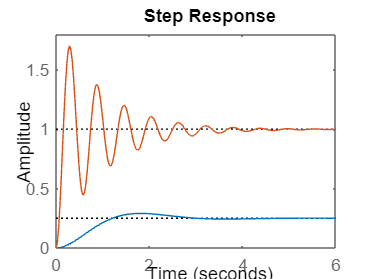

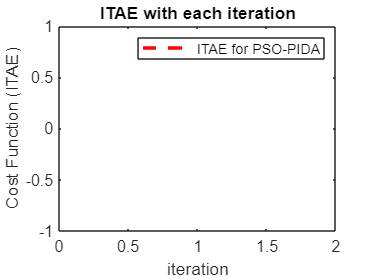


Gc=pid(kp,ki,kd,ka);
Gcf=feedback(Gc*G,1);
step(Gcf);